% Here you'll be designing and validating a pathway. Include figures
% which validate that your system fulfills the design requirements. I'm not
% going to ask for specific figures, I want you to figure out what's
% needed.
% YOU MUST include pathway diagrams AS PART OF THE PDF report. Cell-phone
% pictures of paper sketches are fine.

When designing a pathway, you may utilize only Binding reactions (Mass-Action kinetics), and Enzyme kinetics. The reactions may be reversible or irreversible (including diagrams).

Files you have:

- andpathwaysimple.m

- andpathway.m

- studyresponsetime.m

You will submit:

- *orpathwaysimple.m* and orpathwaysimple2.m

- *orpathway.m* (no need if you have the orpathwaysimple2.m)

- *studyresponsetime_orpathway*.m

- xorpathwaysimple.m and xorpathwaysimple2.m

- xorpathway.m (no need if you have the xorpathwaysimple2.m)

- studyresponsetime_xorpathway.m

- hw5.mlx based on the hw5_template_final.mlx

## Or Pathway

This is another  input pathway. It should respond with "positive" if either Stimulus 1 or Stimulus 2 is present (or both are present). The detection threshold should be 1.0 units of COMBINED input and it should produce a response (>8 units) within 1 second. Assume that the input stimulus concentration remains constant during the simulation.

**OR Pathway Diagram (please draw a new 'or pathway' diagram)  **

**Hint: 1. only three reactions. there is no need for TFPP.**

**          2.  Either S1R1 +TF or S2R2 +TF can reach TFP**

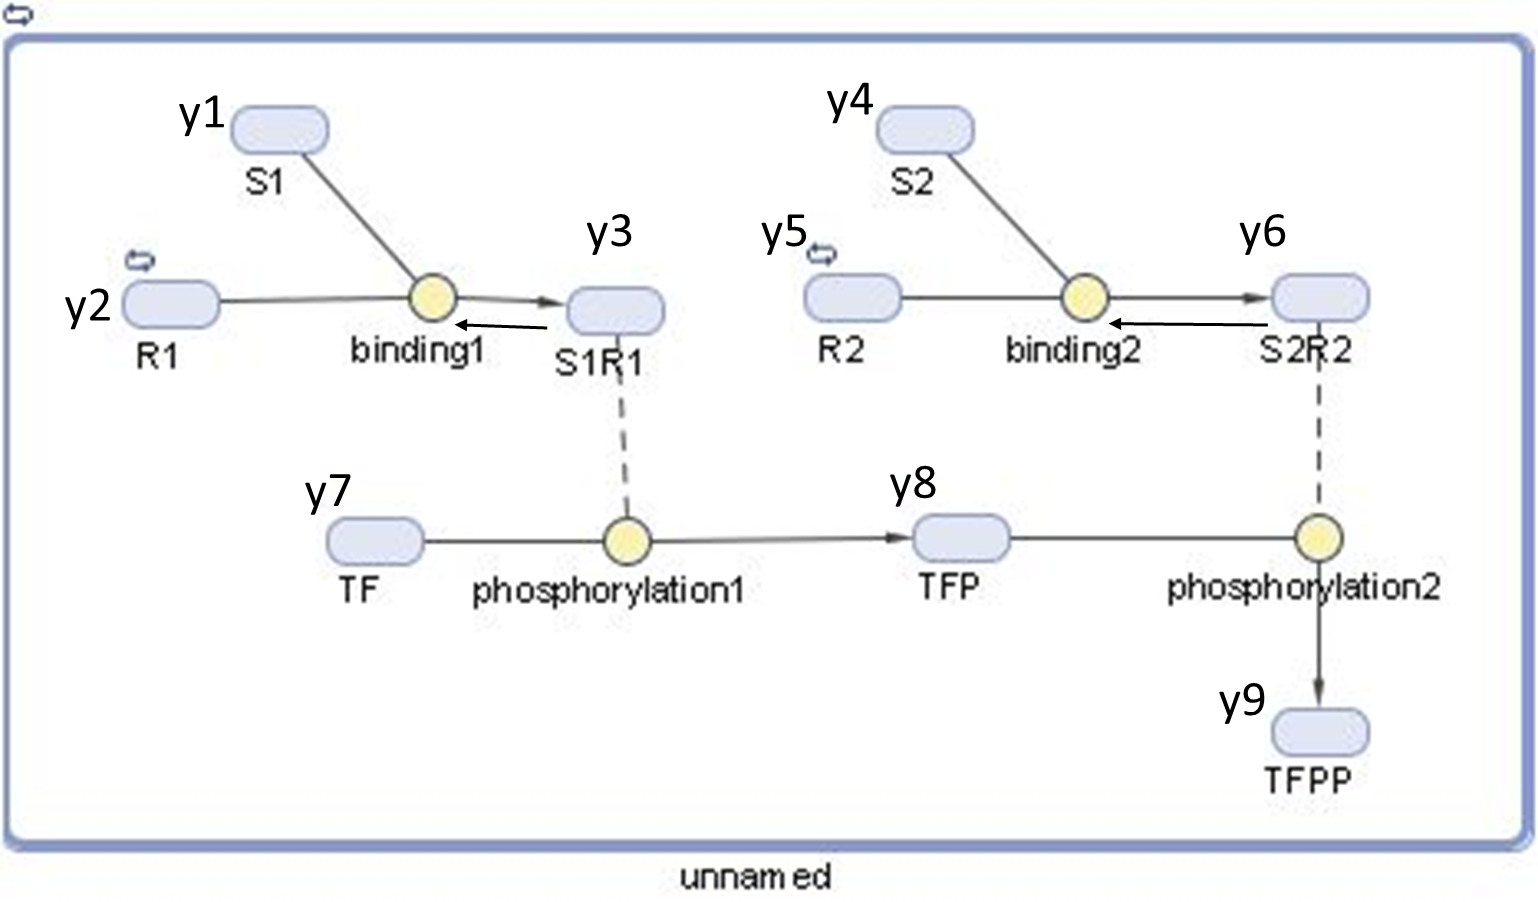

**Write the orpathwaysimple.m**

**kf = 1;  Vmax = 1;kr = 2; km = 2;**

% Function dy = orpathwaysimple(t, y, kf, Vmax)
% the species in y:
% S1, R1, R1S1, S2, R2, R2S2, TF, TFP, 




%arbitrary constants. The magitudes are not important.
% if ~exist('kf', 'var'); kf = 8; end
% if ~exist('Vmax', 'var'); Vmax = 2; end
% kr = 4;
% km = 2;

% re1 = kf*y(1)*y(2) - kr*y(3);
% re2 = kf*y(4)*y(5) - kr*y(6);
% re3 =.....



## **Running** the pathway

% First we need some initial conditions
% Y0 = zeros(?,?);
Y0([2, 5, 7]) = 10;

% Then we need to simulate each of the four conditions.

% no stimulation
Y0([1, 4]) = [0, 0];
[T, Y] = ode23s(@orpathwaysimple, [0, 5], Y0);

% stimulation of receptor 1 only 
Y0([1, 4]) = [9, 0];
[Ta, Ya] = ode23s(@orpathwaysimple, [0, 5], Y0);

% stimulation of receptor 2 only
Y0([1, 4]) = [0, 13];
[Tb, Yb] = ode23s(@orpathwaysimple, [0, 5], Y0);

% stimulation of both receptors
Y0([1, 4]) = [9, 13];
[Tab, Yab] = ode23s(@orpathwaysimple, [0, 5], Y0);

% And now we need to plot the values, T vs. Y.
bmes_fig fourcases
subplot(2,2, 1), 

subplot(2,2,2), 

subplot(2,2,3), 

subplot(2,2,4), 

**Conclusion: What are the differences comparing to andpathway? **

**Plot the product concentration vs. time**

bmes_fig responsetimes1
clf
% Get Response time of a single simulation.
Y0([1, 4]) = [1, 1];
[T, Y] = ode23s(@orpathwaysimple, [0, 10], Y0);


**Check detection time threshold (studyresponsetime function)**

**You need to modify the studyresponsetime.  In this case,  rename it to studyresponsetime_orpathway**

bmes_fig responsetimes2
studyresponsetime_orpathway(@orpathwaysimple);

**Conclusions: Does it satisfy the design requirement, 1 unit input of (Y0[1,4]=1) with the response time of 1 second to reach 8 units of the product?**

## Make the reaction faster to achieve the required response time

Create  a modifiedorpathway by writing an universal orpathway to increase vmax from 2 to 4

bmes_fig responsetimes3
modifiedpathway = @(t,y)orpathway(t,y, 'kf',1, 'vmax',4);
studyresponsetime_orpathway(modifiedpathway);

Or simply change the vmax=4 from vmax=1 from the orpathwaysimple and rename to orpathwaysimple2

bmes_fig responsetimes2
studyresponsetime_orpathway(@orpathwaysimple2);

**Conclusions: Does it satisfy the design requirement with the above change, 1 unit input with the response time of 1 second to reach 8 units of the product? why? estimate the actual response time based on the graph.**

**XOR Pathway**

**XOR Pathway Diagram (please draw a new 'xor pathway' diagram)  **

**Hint:  1. There is no need for TFPP.**

**          2.  Either S1R1 +TF or S2R2 +TF can reach TFP**

**          3.  S1R1 +TF + S2R2 +TF  can not reach TFP**

**write the xorpathwaysimple.m**

% Function dy = xorpathwaysimple(t, y, kf, Vmax)
% the species in y:
% S1, R1, R1S1, S2, R2, R2S2, TF, TFP, 




%arbitrary constants. The magitudes are not important.
% if ~exist('kf', 'var'); kf = 50; end
% if ~exist('Vmax', 'var'); Vmax = 4; end
% kr = 2;
% km = 2;

% re1 = kf*y(1)*y(2) - kr*y(3);
% re2 = kf*y(4)*y(5) - kr*y(6);
% re3 =.....


**Running the pathway**

% First we need some initial conditions
% Y0 = zeros(?,?);
Y0([2, 5, 7]) = 10;

% Then we need to simulate each of the four conditions.

% no stimulation
Y0([1, 4]) = [0, 0];
[T, Y] = ode23s(@xorpathwaysimple, [0, 5], Y0);

% stimulation of receptor 1 only 
Y0([1, 4]) = [9, 0];
[Ta, Ya] = ode23s(@xorpathwaysimple, [0, 5], Y0);

% stimulation of receptor 2 only
Y0([1, 4]) = [0, 13];
[Tb, Yb] = ode23s(@xorpathwaysimple, [0, 5], Y0);

% stimulation of both receptors
Y0([1, 4]) = [9, 13];
[Tab, Yab] = ode23s(@xorpathwaysimple, [0, 5], Y0);

% And now we need to plot the values,T vs. Y.
bmes_fig fourcases
subplot(2,2, 1), 

subplot(2,2,2), 

subplot(2,2,3), 

subplot(2,2,4), 

**Conclusions: What are the differences comparing to andpathway, orpathway?**

**Now using  kf = 8;  Vmax = 4; kr = 2; km = 2; rerun and replot the above pathway. what happens? is the new  xorpathyway better or worse ? why? **

**Check detection time threshold (studyresponsetime function) with xorpathwaysimple.**

**You need to modify the studyresponsetime.  In this case,  rename it to studyresponsetime_xorpathway**

bmes_fig responsetimes2
studyresponsetime_xorpathway(@xorpathwaysimple);

**Conclusions: Does it satisfy the design requirement, 1 unit input with the response time of 1 second to reach 8 units of the product?**